# Wheat Seed Kernels

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data, then extracts the numeric data into a matrix and the existing group numbers into a vector.

data = readtable("./data/seeds.csv");
numData = data{:, 1:end-1};
variety = data.variety;

## Task 1

Numeric data is stored in the matrix `numData`. Use this matrix for the following calculations.

grpK = kmeans(numData, 3);

gmModel = fitgmdist(numData, 3);
grpGMM = cluster(gmModel, numData);

Z = linkage(numData);
grpTree = cluster(Z, "maxclust", 3);

Plot data by group using local function `plotClusters`.

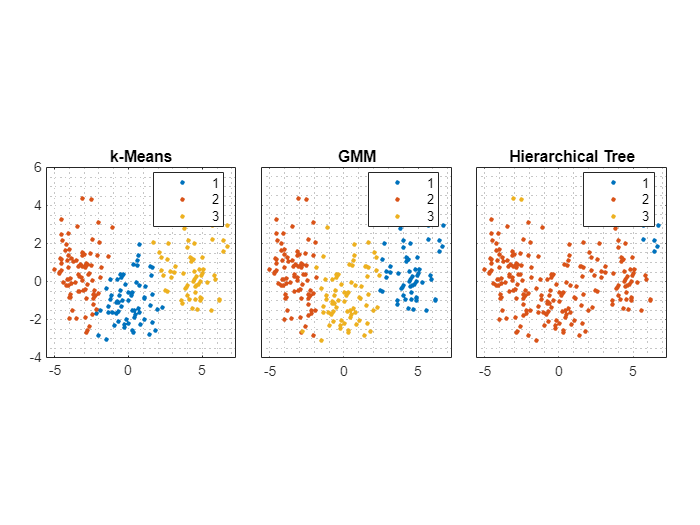

plotClusters(numData,grpK,grpGMM,grpTree)

Plot cross-tabulation values using local function `plotCrosstabs`.

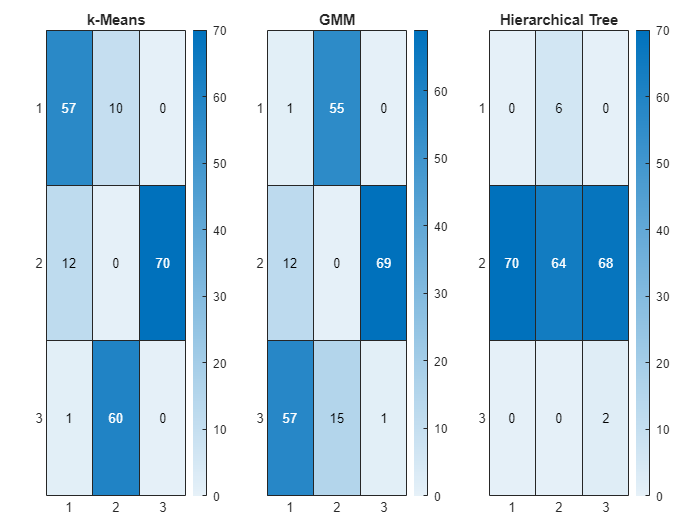

plotCrosstabs(variety,grpK,grpGMM,grpTree)

This function creates side-by-side grouped scatter plots of the transformed data.

function plotClusters(data,gk,gm,gt)
    [~,scrs] = pca(data);
    sz = 8;
    
    clf
    tiledlayout(1,3,"TileSpacing","compact","Padding","compact");
    
    ax(1) = nexttile;
    gscatter(scrs(:,1),scrs(:,2),gk,[],[],sz)
    grid minor
    title("k-Means")
    
    ax(2) = nexttile;
    gscatter(scrs(:,1),scrs(:,2),gm,[],[],sz)
    grid minor
    title("GMM")
    
    ax(3) = nexttile;
    gscatter(scrs(:,1),scrs(:,2),gt,[],[],sz)
    grid minor
    title("Hierarchical Tree")
    
    axis(ax,"square")
    yticklabels(ax(2:end),[])
    figure
end

This function creates side-by-side heatmaps of the cross-tabluation values.

function plotCrosstabs(cats,gk,gm,gt)
    clf
    t = tiledlayout(1,3,"TileSpacing","compact","Padding","compact");
    
    ax(1) = nexttile;
    heatmap(crosstab(gk,cats))
    title("k-Means")
    
    ax(2) = nexttile;
    heatmap(crosstab(gm,cats))
    title("GMM")
    
    ax(3) = nexttile;
    heatmap(crosstab(gt,cats))
    title("Hierarchical Tree")
    
    figure
end